close all
clear
clc

定义常量

E = 1;
T1 = 1;
omg1 = 2*pi/T1;

生成采样时刻和去掉直流分量的矩形脉冲

N = 1000;
t = linspace(-T1/2,T1/2-T1/N,N)';
f = E*(t>-T1/4&t<T1/4) - E/2;

计算指数形式的傅里叶级数系数F_{-10}到F_{10}

k1 = -10;
k2 = 10;
k = [k1:k2]';
F = 1/N*exp(-1j*k*omg1*t.')*f;

转换成三角函数形式的傅里叶级数系数，去掉为零的虚部避免警告

a0 = F(11);
ak = F(12:21) + F(10:-1:1);
ak = real(ak);

生成前5个三角函数基波并合成矩形脉冲

fs = cos(t*[0:5]*omg1)*[a0;ak(1:5)];

绘制时域波形（左子图）和频谱（右子图）

其中波形包括矩形脉冲、前5个基波合成的矩形脉冲，以及各个基波

频谱即傅里叶级数系数

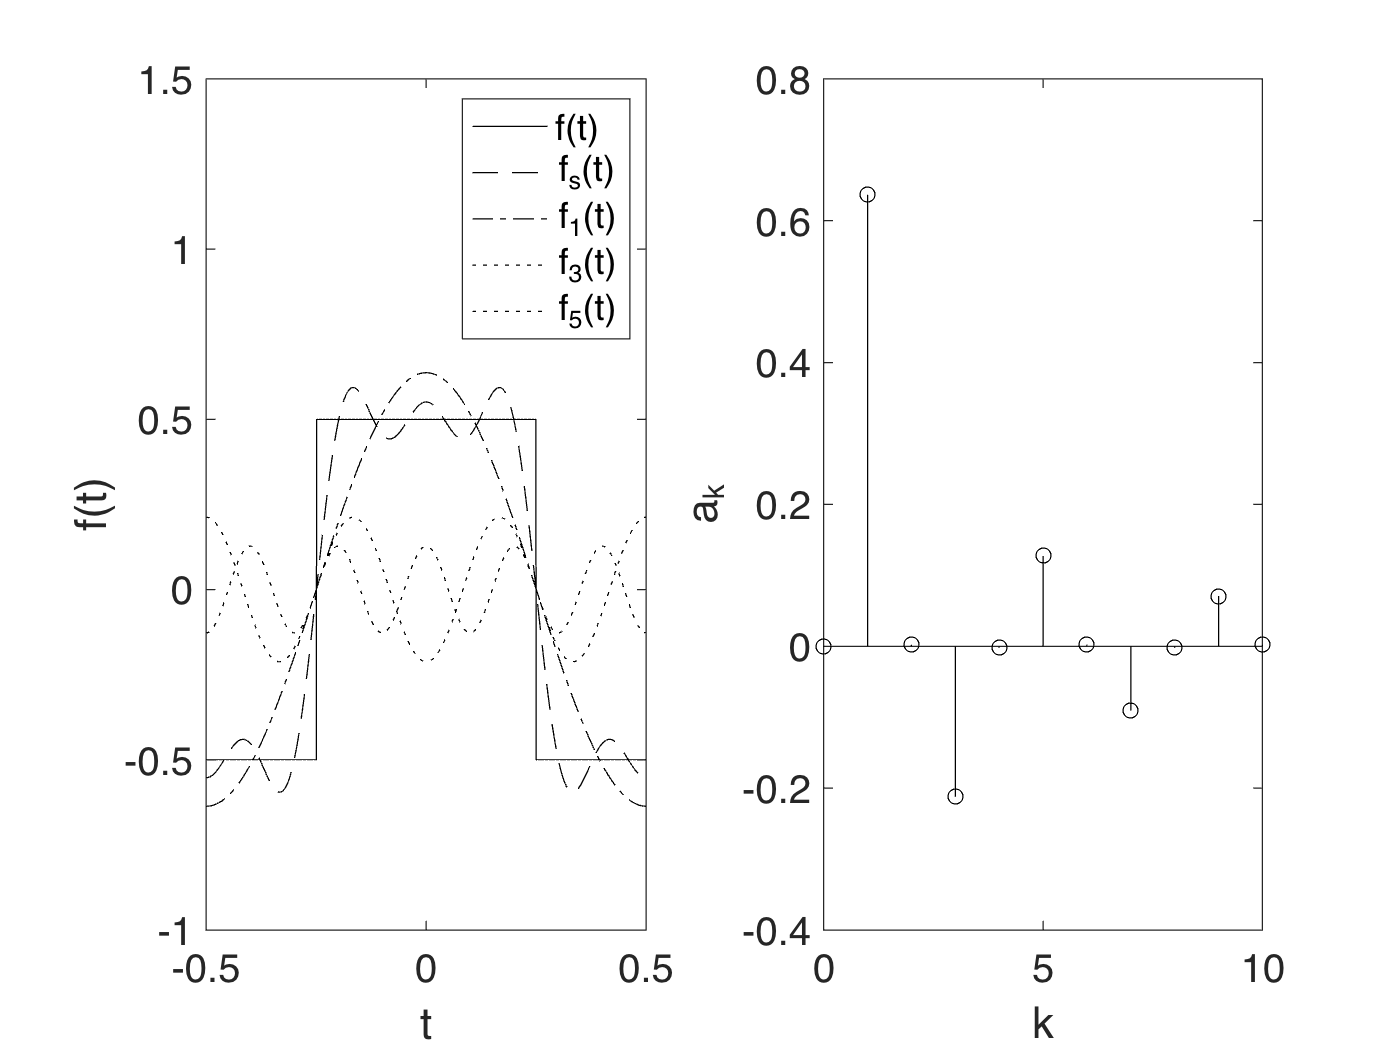

figure;
subplot(1,2,1), hold on, box on;
plot(t,f,'k-');
plot(t,fs,'k--');
plot(t,ak(1)*cos(omg1*t),'k-.');
plot(t,ak(3)*cos(3*omg1*t),'k:');
plot(t,ak(5)*cos(5*omg1*t),'k:');
legend('f(t)','f_s(t)','f_1(t)',...
    'f_3(t)','f_5(t)');
set(gca,'YLim',[-1, 1.5],'FontSize',16);
xlabel('t');
ylabel('f(t)');
subplot(1,2,2), hold on, box on;
stem([0:10],[a0;ak],'k');
set(gca,'FontSize',16);
xlabel('k');
ylabel('a_k');